# Git integration

Git is a powerful version control system that enables users to track changes, collaborate efficiently, and maintain a comprehensive history of their codebase. By using Git, developers can experiment with new features, fix bugs, and revert to previous versions without fear of losing work. For MATLAB users, Git offers significant advantages, such as seamless collaboration on scripts, functions, and Simulink models, even when working in large teams or across different locations. It helps prevent conflicts, ensures reproducibility of results, and integrates well with MATLAB’s own interface and external platforms like GitHub, making it easier to manage research projects, share code, and maintain high-quality, well-documented workflows.

## Git integration from MATLAB

MATLAB offers several ways to [integrate with Git](https://se.mathworks.com/help/matlab/matlab-git-source-control.html), catering to different workflows and preferences. First option is to use MATLAB Projects, which provide a dedicated interface for source control, allowing users to initialize a Git repository, manage branches, and perform commits directly within the Project window. This approach is ideal for organizing larger codebases and collaborating with teams. Secondly, users can enable source control in the Current Folder browser, which allows Git operations—such as commit, push, and pull—on any folder, even outside of a formal MATLAB Project. Thirdly, for those who prefer more flexibility, MATLAB also supports working with Git via the command line, while still editing and running code in MATLAB. These integration options make it easy for users to adopt Git in a way that best fits their project size, structure, and workflow.

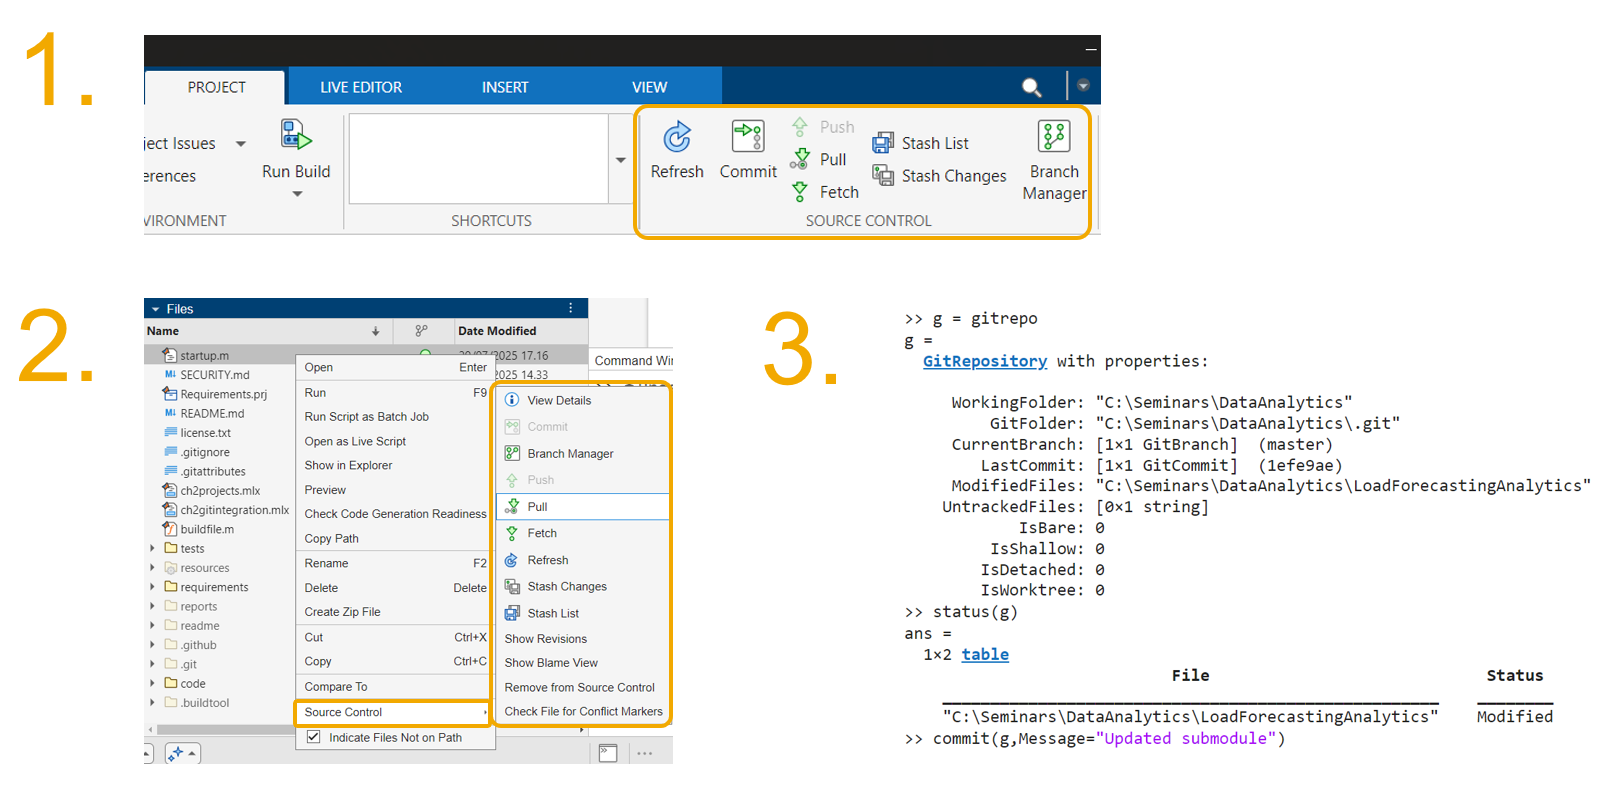

## Using Git programmatically

Let's interact with the existing Git repository using MATLAB's programmatic API for Git.

% Create a repository object
g = gitrepo

## See operations you can use

methods(g)

## Look at the history of the repo

g.log

## Create a new branch

Using branches with Git allows you to work on new features, bug fixes, or experiments without affecting the main codebase. Branches create isolated environments where changes can be made safely and independently, making it easier to test ideas, collaborate with others, and manage multiple development tasks at once. Once the work on a branch is complete and tested, it can be merged back into the main branch.

To do this with MATLAB, we can use the [`createBranch()`](https://se.mathworks.com/help/matlab/ref/matlab.git.gitrepository.createbranch.html) 

b = createBranch(g,"newBranch")

## Switch to the new branch

switchBranch(g,b)

## Create a new file and add it to the repo

save("datafile.mat")
add(g,"datafile.mat")

## Commit the changes

commit(g,"Message","Added a data file")

## Switch to another branch

We can switch to another branch, say, the main branch. What happens to the file we created in the other branch?

switchBranch(g,"main")

## Delete the new branch

deleteBranch(g,"newBranch")
